close("all"); clear; clc;
setmadsympath();

speed = 130;
root = "G:\My Drive\BikeSimResults\BigSports\DLC\";
dir = root + "Vx" + speed + "Kph\";
ref = readtable(dir + "bikesim_results_"+ speed + "kph");

params = bigSportsParameters();
p = bikeSimToPrydeParameters(params,speed/3.6);

params = [
    p.a;
    p.an;
    p.b;
    p.rf;
    p.rr;
    p.tf;
    p.tr;
    p.caster
    ].';

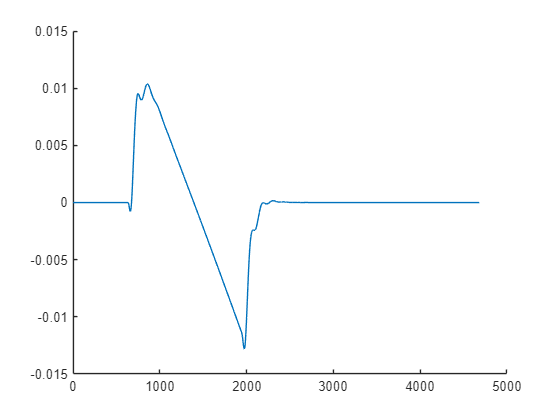

yaw = deg2rad(ref.Yaw);
pitch = deg2rad(ref.Pitch);
roll = deg2rad(ref.Roll_E);
R = angle2dcm(yaw,pitch,roll);
[yaw,lean,pitch] = dcm2angle(R,'ZXY');

steer = deg2rad(ref.Steer);

wx = deg2rad(ref.AVx);
wy = deg2rad(ref.AVy);
wz = deg2rad(ref.AVz);
ws = -ref.M_StrSys./p.Cdelta;

x = [yaw,lean,pitch,steer];
u = [wx,wy,wz];

x_est = zeros(size(x));
n = numel(yaw);

fM = @steeringEstimationMassMatrix;
ff = @steeringEstimationForcingVector;

for k = 1:n
    M = fM(x(k,:),u(k,:),params);
    f = ff(x(k,:),u(k,:),params);
    x_est(k,:) = M\f;
end

ws_est = x_est(:,4);
ws_est(ws_est == inf) = 0;
ws_est(isnan(ws_est)) = 0;
ws_est = filloutliers(ws_est,"linear");

hold on
plot(ws)
plot(ws_est)
hold off